clearvars
Dm = 5.56 * 10^(-2); %アンテナ間隔 ≒波長/2
Lm = 1000 * 1000; %距離 1000km
theta = pi * 3 / 6 ;
%dm = Dm * cos(theta);
freqHz = 2.675 * 10^9; %周波数
c = 3.0 * 10 ^ 8; %光速
lambdam = c/freqHz; %波長
amplititude1 = 0

amplititude1 = 0

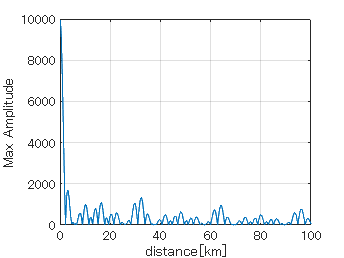

plot_x =0.1:0.1:100;
parfor h=1:1:1000
    %ht = h * 0.1; %0.1倍で0.1km刻みに
    ht = h * 1000 *0.1
    %for i=1:200
        %hypotenuse = sqrt((ht) ^ 2 + 5000 ^ 2);
        %amplititude1 = 1 * cos(2 * pi * freqHz * (i*10^(-11) - (hypotenuse/c))); %真ん中のやつ
        %amplititude2 = 1 * cos(2 * pi * freqHz * (i*10^(-11) - (Lm/c - (dm / c))));
        %sum = 0 ;
        res = zeros(200,1);
        number_of_satel = struct('k',[800 1600 2000 2400 3200]);
        for j = number_of_satel.k
            radius = Dm * j / (pi * 2);
            %radius2 = sqrt( (Dm ^2) / (2 * (1 - cos(2 * pi / j))));

            for each_satel = 1:j
                x = radius * cos(2 * pi * each_satel / j);
                y = radius * sin(2 * pi * each_satel / j);
                hypotenuse = sqrt((x - ht) ^ 2 + y ^ 2 + Lm ^2 );
                % tandelta = atan(hypotenuse / Lm); %θ求める
                % % theta_cir = atan(radius / Lm);
                % %theta_for_circle = theta + theata_cir;
                % dm = Lm * cos(tandelta);
                %sum = 0
                for i=1:200
                    amplititudefor=cos(2 * pi * freqHz * (i*(1/(freqHz*200)) - (hypotenuse / c)));
                    %sum = amplititudefor + sum;
                    res(i) = res(i) + amplititudefor;
                end

            end
        end
        
        %sum = sum + amplititude1;
        %result(i) = sum;
    %end
    max_result(h) = max(res); %波の最大
end
%nnz(max_result> 600)
       %plot(result)
%h=1:1:100;
plot(plot_x,max_result)
%semilogy(h*0.1,max_result) %対数グラフ
grid on
xlabel("distance[km]")
ylabel("Max Amplitude")